y = [10.0634 6.0791 4.2923 3.3476 2.8752 ]

y =    10.0634    6.0791    4.2923    3.3476    2.8752


x = [1/40 1/80 1/120 1/160 1/200]

x =     0.0250    0.0125    0.0083    0.0063    0.0050



fg2 = figure

fg2 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


hold on
grid on
plot(x, y, '+r');
xi = min(0):0.001:max(x);
N = 1; % степень
coeff1 = polyfit(x, y, N)

coeff1 =   358.4812    1.2389


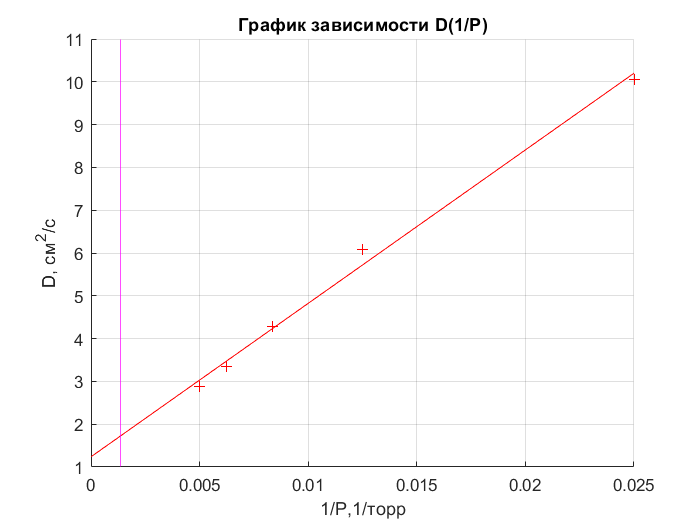

y2 = 0;
for k=0:N
    y2 = y2 + coeff1(N-k+1) * xi.^k;
end
gr1 = plot(xi, y2, 'r'); 
xlabel(['1/P,1/торр'])
ylabel("D, см^2/c")
title("График зависимости D(1/P)")
hold off 
set(fg2, "Visible", 'on')
xline(1/748, 'm')

scatter